clc;close all;clear;

## Create data

Generates a dataset consisting of three different clusters of data points, each drawn from a multivariate normal distribution with specified means and covariances.

## Defining the Means

mu1 = [1 2];
mu2=[-2 -3];
mu3=[6 6];  

**mu1, mu2, mu3** are the mean vectors for three different clusters of data points in a 2-dimensional space.

- `mu1 = [1 2]`: The mean of the first cluster is at the point (1, 2).

- `mu2 = [-2 -3]`: The mean of the second cluster is at the point (-2, -3).

- `mu3 = [6 6]`: The mean of the third cluster is at the point (6, 6).

### Defining the Covariance Matrices

sigma1 = [3 0; 0 2];
sigma2 = sigma1;
sigma3 = sigma1;

**sigma1, sigma2, sigma3** are the covariance matrices for the three clusters. The covariance matrix defines the shape, orientation, and spread of the data around the mean.

- `sigma1 = [3 0; 0 2]`: This covariance matrix indicates that the first cluster's data has a variance of 3 in the first dimension (x-axis) and 2 in the second dimension (y-axis). The zero off-diagonal elements indicate no correlation between the two dimensions.

- `sigma2` and `sigma3` are set equal to `sigma1`, meaning that all three clusters share the same covariance structure.

### Defining the Number of Data Points

n1 = 100;
n2 = 100;
n3 = 100;

### Generating the Data

X = [mvnrnd(mu1,sigma1,n1); mvnrnd(mu2,sigma2,n2); mvnrnd(mu3,sigma3,n3)];
labels = [ones(n1,1); 2*ones(n2,1); 3*ones(n3,1)];

**mvnrnd(mu, sigma, n)** is a MATLAB function that generates `n` samples from a multivariate normal distribution with mean `mu` and covariance matrix `sigma`.

- `mvnrnd(mu1,sigma1,n1)`: Generates 100 data points for the first cluster using `mu1` and `sigma1`.

- `mvnrnd(mu2,sigma2,n2)`: Generates 100 data points for the second cluster using `mu2` and `sigma2`.

- `mvnrnd(mu3,sigma3,n3)`: Generates 100 data points for the third cluster using `mu3` and `sigma3`.

matrix `X` is of size `300 x 2`, where each row is a 2-dimensional data point.

Create a vector called `labels` that assigns a class label to each data point in the dataset `X`.

- `labels` is a `300 x 1` vector where each element is an integer label indicating the cluster to which the corresponding data point in `X` belongs.

- The first 100 elements are `1`, indicating that the first 100 data points in `X` belong to the first cluster.

- The next 100 elements are `2`, indicating that the next 100 data points belong to the second cluster.

- The last 100 elements are `3`, indicating that the final 100 data points belong to the third cluster.

### Plot the data

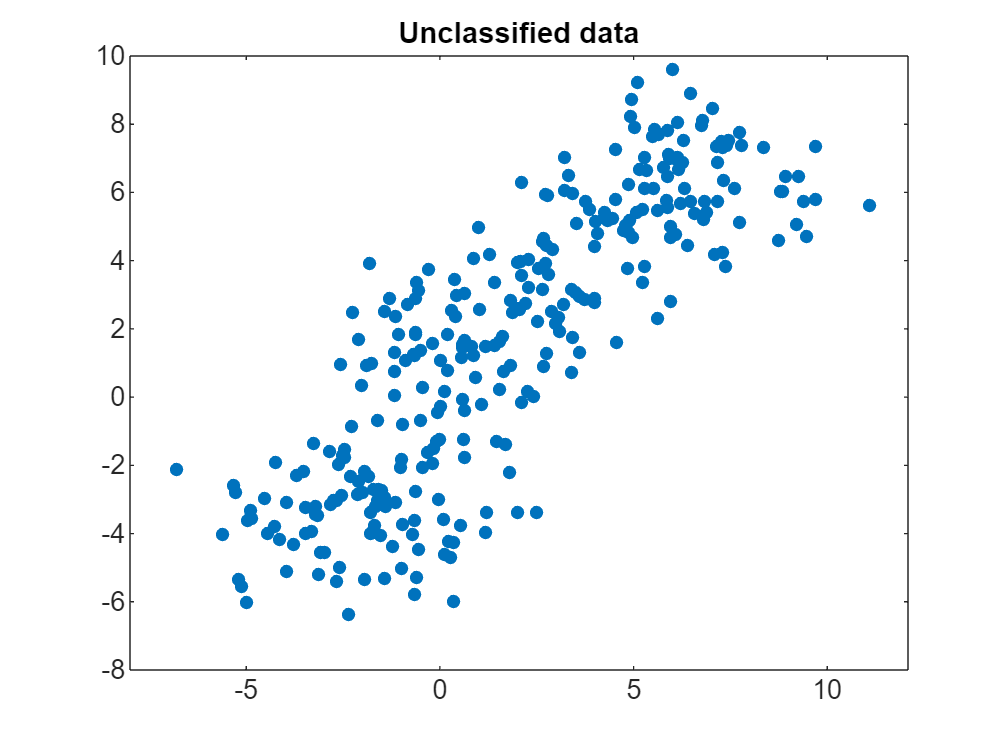

gscatter(X(:,1),X(:,2))
% gscatter(X(:,1),X(:,2),labels) 
title('Unclassified data');

### Fitting the LDA Model

LDA = fitcdiscr(X,labels,'DiscrimType','linear');

`fitcdiscr(X, labels, 'DiscrimType', 'linear')`**:**

- `fitcdiscr` is a MATLAB function that fits a discriminant analysis classifier to the data.

- `X` is the matrix of feature data, where each row represents an observation and each column represents a feature.

- `labels` is the vector of class labels corresponding to each observation in `X`.

- `'DiscrimType', 'linear'` specifies that a linear discriminant analysis (LDA) should be performed. This means the algorithm will find linear decision boundaries to separate the classes.

The linear decision boundary between two classes can be expressed as:


$$a_{1\;} X_1 +a_{2\;} X_2 +\;\ldotp \ldotp \ldotp \;+a_n X_n +b=0$$


The equation $a\times \mathit{\mathbf{X}}+b=0$ represents the decision boundary between class `1` and class `2`. Any data point for which this equation is positive will be classified as belonging to one class, while a negative value indicates membership in the other class.

#### Coefficients for the decision boundary between class `1` and class `2`

b12 = LDA.Coeffs(1,2).Const;  
a12 = LDA.Coeffs(1,2).Linear;

#### Coefficients for the decision boundary between class `1` and class 3

b13 = LDA.Coeffs(1,3).Const;  
a13 = LDA.Coeffs(1,3).Linear;

### Plotting the Decision Boundary

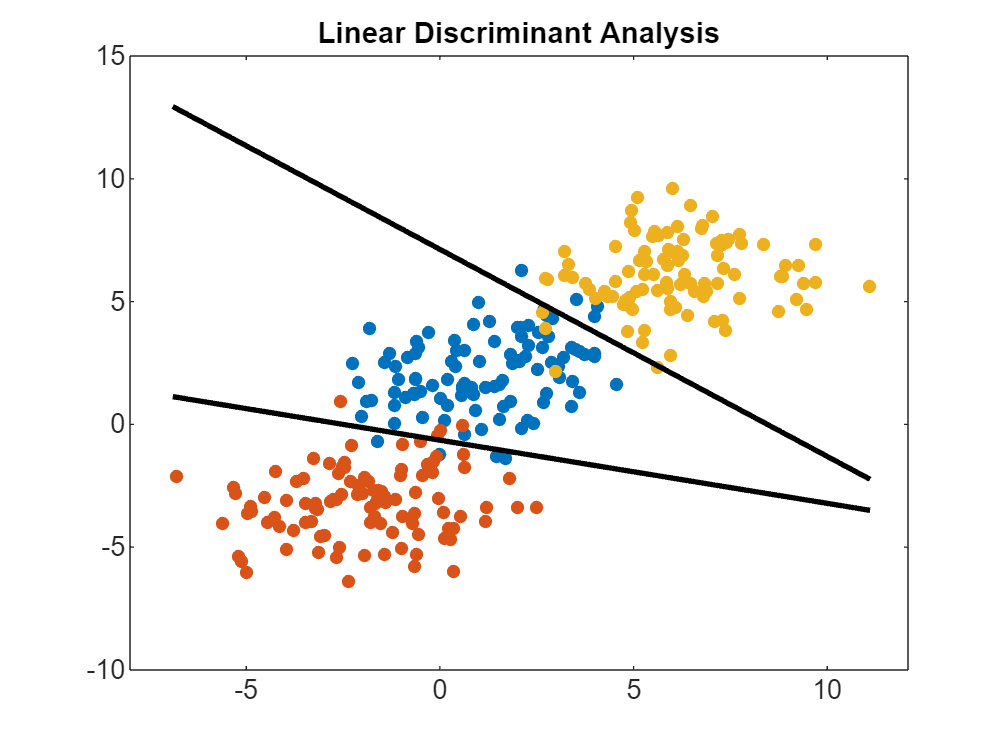

gscatter(X(:,1),X(:,2),labels) 
title('Linear Discriminant Analysis');
hold on

xx=min(X(:,1))-0.1:0.1:max(X(:,1))+0.1;

yy12=-(a12(1)*xx+b12)/a12(2);  % a(1)*x1+a(2)*x2+b=0
plot(xx,yy12,'k-','LineWidth',2)

yy13=-(a13(1)*xx+b13)/a13(2);
plot(xx,yy13,'k-','LineWidth',2)
legend off;
hold off;

### Fitting the QDA Model

QDA = fitcdiscr(X,labels,'DiscrimType','quadratic');

- The `fitcdiscr` function with `'DiscrimType', 'quadratic'` fits a QDA model to the data, allowing for non-linear, quadratic decision boundaries.

The decision boundary between two classes is a quadratic equation that can be expressed as:


$$a_1 X_1^2 +a_2 X_2^2 +a_3 X_1 X_2 +b_1 X_1 +b_2 X_2 +c=0$$


K12 = QDA.Coeffs(1,2).Const;
L12 = QDA.Coeffs(1,2).Linear;
Q12 = QDA.Coeffs(1,2).Quadratic;

K13 = QDA.Coeffs(1,3).Const;
L13 = QDA.Coeffs(1,3).Linear;
Q13 = QDA.Coeffs(1,3).Quadratic;

- `K = QDA.Coeffs(1,2).Const: `Extracts the constant term (intercept) of the quadratic decision boundary between class `1` and class `2`.

- `L = QDA.Coeffs(1,2).Linear: `Extracts the linear coefficients for the features in the decision boundary.

- `Q = QDA.Coeffs(1,2).Quadratic: `Extracts the quadratic coefficients for the decision boundary. `Q` is a 2x2 matrix where:

- `Q(1,1)` is the coefficient for the $x_1^2$� term.

- `Q(2,2)` is the coefficient for the $x_2^2$� term.

- `Q(1,2)` and `Q(2,1)` are the coefficients for the cross term $x_1 \times x_2$�.

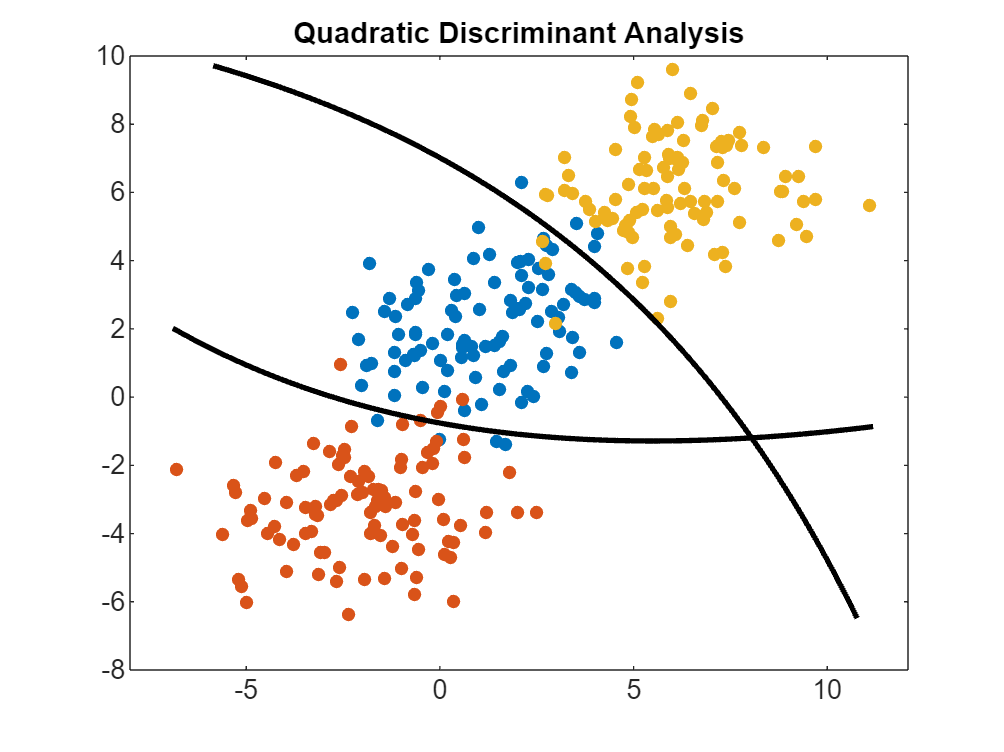

gscatter(X(:,1),X(:,2),labels) 
title('Quadratic Discriminant Analysis');
hold on

xx=min(X(:,1))-0.1:0.1:max(X(:,1))+0.1;

f12 = @(x1,x2) K12 + L12(1)*x1 + L12(2)*x2 + Q12(1,1)*x1.^2 + (Q12(1,2)+Q12(2,1))*x1.*x2 + Q12(2,2)*x2.^2;
h12 = fimplicit(f12,[min(X(:,1))-0.1 max(X(:,1))+0.1 min(X(:,2))-0.1 max(X(:,2))+0.1]);
h12.Color = 'k';
h12.LineWidth = 2;

f13 = @(x1,x2) K13 + L13(1)*x1 + L13(2)*x2 + Q13(1,1)*x1.^2 + (Q13(1,2)+Q13(2,1))*x1.*x2 + Q13(2,2)*x2.^2;
h13 = fimplicit(f13,[min(X(:,1))-0.1 max(X(:,1))+0.1 min(X(:,2))-0.1 max(X(:,2))+0.1]);
h13.Color = 'k';
h13.LineWidth = 2;

legend off;

- `f12`: An anonymous function representing the quadratic decision boundary between class 1 and class 2. This function is based on the quadratic coefficients `Q12`, linear coefficients `L12`, and constant term `K12` that were previously calculated from the QDA model.

- `fimplicit(f12, [...])`: This function plots the implicit function `f12` over the specified range. The resulting plot is the quadratic decision boundary between class 1 and class 2.